# Environment

For simulate environment we can load an image, then process it in order to get a binary image and finally convert the image in an Occupancy Grid.

Load an image from disk.

addpath('..\..\.\maps')

image = imread('world1.png');

Convert image into grayscale.

grayimage = rgb2gray(image);

Threshold  image in order to get a binary image.

bwimage = grayimage < 0.1;

Convert image into  binaryOccupancyMap  with scale  (pixes/meter).

map = binaryOccupancyMap(bwimage,10);

Finally create a visualizer and assign  the  binaryOccupancyMap.

viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = .1;

In order to show the map and robot in action we define a similar behavior from previous lesson.


initPose = [ 1; 1; 1.57]; % [x ; y ; theta]    

R = 0.1; 
L = .25; 
mobileRobot = DifferentialDrive(R,L);

Define Sample time, time array and rate control 

sampleTime = 0.1;          % Sample time [s]
tVec = 0:sampleTime:3;     % Time array  in this example te execution will run for 3 seconds
r = rateControl(1/sampleTime);

Velocity definition.

v = .2; % [m/s]
w = pi/4; % [rad/s]
bodyV = [v;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.

### Execute simulation

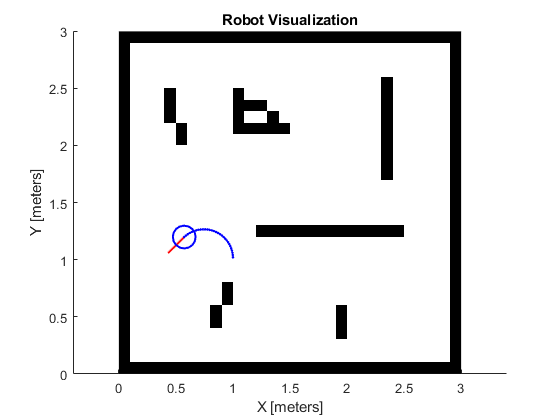

currentPose = initPose;

for idx = 2:numel(tVec) 
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
      
    % Update visualization
    viz(currentPose);
    
    %Wait for visualization rate
    waitfor(r);
    
end